## TO BEGIN

clear all, close all, clc
addpath('time')

## import the neo_api py library

module=py.importlib.import_module('neo_api_function');

## To Reload the Library run this cell

py.importlib.reload(module);

obtain the **sentry risk list**

sentry_risk_names=py.neo_api_function.get_sentry_risk_list();

obtain the **NEOCC esa risk list** (.txt required, can be download by TODO add link)

esa_risk_names=py.neo_api_function.extract_esa_name_from_file("esa_risk_list.txt");

merge risk list

risk_list=py.neo_api_function.merge_risk_lists(esa_risk_names, sentry_risk_names);

query **JPL SBDB** for the bodies in the risk list

dict_risk_list=py.neo_api_function.get_dict(risk_list);

29075 could raise error in importing virtual impact data


**Explore DB**

MOID and Magnitude

MOID_H=py.neo_api_function.MOID_H(dict_risk_list)

2010MY112 does not have magnitude info
2010MZ112 does not have magnitude info
2010MA113 does not have magnitude info


MOID_H =   Python tuple with no properties.

    ([0.023863, 0.000342446, 0.00484466, 0.0027088, 0.00299328, 0.000465933, 0.00138299, 0.012335, 0.00125091, 0.00105179, 0.00843783, 0.0217991, 0.00131586, 0.00199014, 0.000902841, 0.00222756, 0.000386873, 0.0374655, 0.00516786, 0.00330311, 0.00259932, 0.00100642, 0.00286821, 0.011159, 0.00266016, 0.00360636, 0.00206353, 0.000501304, 0.00204344, 0.00212611, 0.00591383, 0.0100471, 0.000852474, 0.000436354, 0.000224438, 0.00121057, 0.00263847, 0.0164127, 0.0118918, 0.0015896, 0.00113629, 0.00992183, 0.00248243, 0.00571679, 0.0294783, 0.000990511, 0.00111357, 0.000973277, 0.000744929, 0.00350668, 0.000365051, 0.00199274, 0.000499886, 0.00373875, 0.0013683, 0.0194417, 0.0017792, 0.00137024, 0.020536, 0.00188783, 0.00137649, 0.000788756, 0.00810998, 0.00138675, 0.00124506, 0.00432215, 0.00920047, 0.000939949, 0.201873, 0.0697112, 0.00294161, 0.00100413, 0.029942, 0.00174338, 0.000

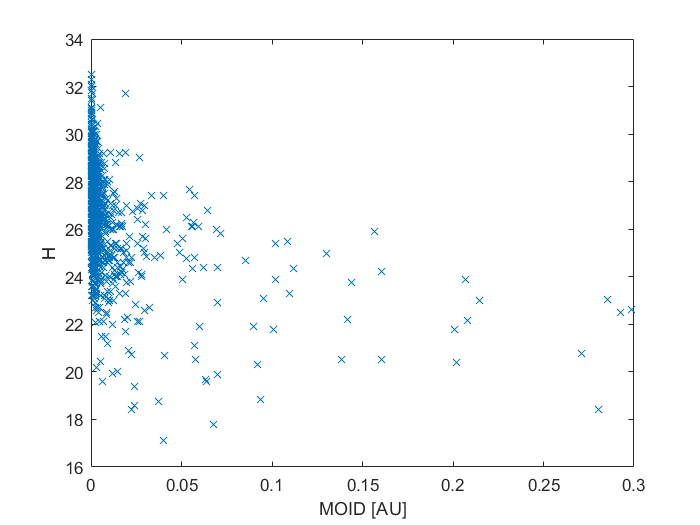

cMOID = cell(MOID_H{1});
MOID = cellfun(@double,cMOID);
cH = cell(MOID_H{2});
H = cellfun(@double,cH);
plot(MOID,H, 'x');

xlabel('MOID [AU]')
ylabel('H')

Magnitude and Orbit Condition Code

H_OCC=py.neo_api_function.H_OCC(dict_risk_list);

2010MY112 does not have magnitude info
2010MZ112 does not have magnitude info
2010MA113 does not have magnitude info


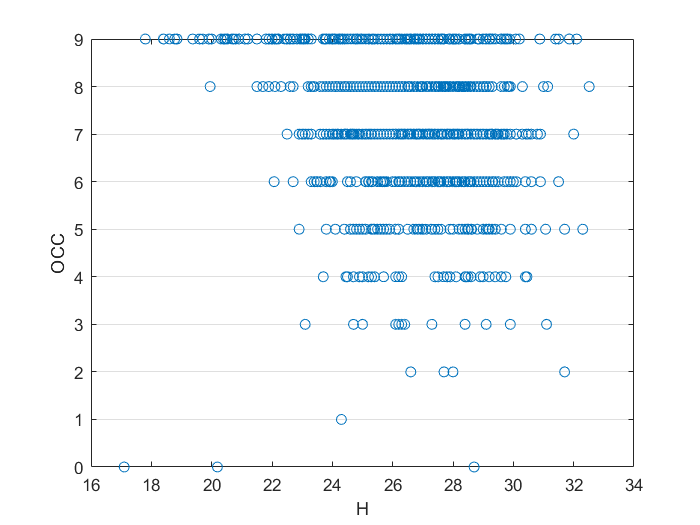

cH = cell(H_OCC{1});
H = cellfun(@double,cH);
cOCC = cell(H_OCC{2});
OCC = cellfun(@double,cOCC);
plot(H,OCC,'o');

set(gca,'XGrid','off','YGrid','on')
xlabel('H')
ylabel('OCC')

## Obtain py dictionair of the selected asteroid and their properties

refined_selected=py.neo_api_function.refined_selection(dict_risk_list);

2012QD8
Max Palermo Scale:-3.88
OCC:7
2005WG57
Max Palermo Scale:-5.46
OCC:7
2012BY1
Max Palermo Scale:-5.56
OCC:8
2012SY49
Max Palermo Scale:-6.13
OCC:7
2008XU2
Max Palermo Scale:-6.23
OCC:7
2008KN11
Max Palermo Scale:-6.26
OCC:7
2020UE
Max Palermo Scale:-6.34
OCC:6
2006HX57
Max Palermo Scale:-6.82
OCC:7
2006SC
Max Palermo Scale:-6.89
OCC:6


refined_selected_dict=refined_selected{1}

refined_selected_dict =   Python dict with no properties.

    {'2012QD8': {'fullname': '(2012 QD8)', 'our_id': 386, 'neo_flag': True, 'orbit_class': 'APO', 'pha_flag': False, 'object_kind': 'au', 'moid': Unit("0.00204637 AU"), 'orbital_elements': OrderedDict([('e', '.6978637301757757'), ('e_sig', '.00018213'), ('a', Unit("1.91263 AU")), ('a_sig', Unit("0.00051114 AU")), ('q', Unit("0.577876 AU")), ('q_sig', Unit("0.00019392 AU")), ('i', Unit("5.58051 deg")), ('i_sig', Unit("0.0055574 deg")), ('om', Unit("348.738 deg")), ('om_sig', Unit("0.021049 deg")), ('w', Unit("87.7732 deg")), ('w_sig', Unit("0.0020581 deg")), ('ma', Unit("26.5511 deg")), ('ma_sig', Unit("1.9618 deg")), ('tp', Unit("2.45913e+06 d")), ('tp_sig', Unit("5.2364 d")), ('per', Unit("966.152 d")), ('per_sig', Unit("0.3873 d")), ('n', Unit("0.372612 deg / d")), ('n_sig', Unit("0.00014937 deg / d")), ('ad', Unit("3.24739 AU")), ('ad_sig', Unit("0.00086785 AU")

refined_selected_name=refined_selected{2}

refined_selected_name =   Python list with no properties.

    ['2006HX57', '2020UE', '2008XU2', '2008KN11', '2006SC', '2005WG57', '2012SY49', '2012BY1', '2012QD8']


Find mission for given asteroid

    req_mjd0 = 59215; % from 2021
    req_duration = 365*7; % to 2028
    req_min_tof = 100;
    req_max_tof = 365*10;
    req_step_size = 10;
    missions_dict=py.neo_api_function.bi_impulsive_mission(refined_selected_name, py.int(req_mjd0), py.int(req_duration),py.int(req_min_tof),py.int(req_max_tof),py.int(req_step_size))

missions_dict =   Python dict with no properties.

    {'2006HX57': {'missions': {'0': {'fullname': '(2006 HX57)', 'mjd0': 60779, 'mjdf': 61064, 'tof': 285, 'vinf_dep': 12.2471, 'vinf_arr': 23.6762, 'earth_dist': 2.0386, 'phase_ang': 167.49, 'elong_arr': 21.66, 'decl_dep': -7.97, 'approach_ang': 124.73}, '1': {'fullname': '(2006 HX57)', 'mjd0': 61764, 'mjdf': 61859, 'tof': 95, 'vinf_dep': 12.203, 'vinf_arr': 20.4748, 'earth_dist': 0.7274, 'phase_ang': 8.19, 'elong_arr': 67.82, 'decl_dep': -22.54, 'approach_ang': 111.16}, '2': {'fullname': '(2006 HX57)', 'mjd0': 59459, 'mjdf': 59629, 'tof': 170, 'vinf_dep': 12.1609, 'vinf_arr': 18.6609, 'earth_dist': 2.4392, 'phase_ang': 8.33, 'elong_arr': 93.48, 'decl_dep': 21.34, 'approach_ang': 75.57}, '3': {'fullname': '(2006 HX57)', 'mjd0': 61299, 'mjdf': 61469, 'tof': 170, 'vinf_dep': 12.0616, 'vinf_arr': 20.4733, 'earth_dist': 2.5156, 'phase_ang': 7.25, 'elong_arr': 89.68, 'decl_dep'

%{
name=[];
    for i=1:int(py.len(refined_selected_name))
        
        cname=cell(missions_dict{refined_selected_name{i}})
        name(i)=cellfun(@string, cname)
    end
%}


% TODO
missions_dict{refined_selected_name{1}}.keys()

ans =   Python dict_keys with no properties.

    dict_keys(['missions', 'porkchop_dv', 'dep_date', 'tof', 'mp_min_dv'])


py_pc_dv = missions_dict{refined_selected_name{1}}{'porkchop_dv'};
pc_dv = double(py_pc_dv);
py_dep_date = missions_dict{refined_selected_name{1}}{'dep_date'}

py_dep_date =   Python list with no properties.

    [59215.0, 59225.0, 59235.0, 59245.0, 59255.0, 59265.0, 59275.0, 59285.0, 59295.0, 59305.0, 59315.0, 59325.0, 59335.0, 59345.0, 59355.0, 59365.0, 59375.0, 59385.0, 59395.0, 59405.0, 59415.0, 59425.0, 59435.0, 59445.0, 59455.0, 59465.0, 59475.0, 59485.0, 59495.0, 59505.0, 59515.0, 59525.0, 59535.0, 59545.0, 59555.0, 59565.0, 59575.0, 59585.0, 59595.0, 59605.0, 59615.0, 59625.0, 59635.0, 59645.0, 59655.0, 59665.0, 59675.0, 59685.0, 59695.0, 59705.0, 59715.0, 59725.0, 59735.0, 59745.0, 59755.0, 59765.0, 59775.0, 59785.0, 59795.0, 59805.0, 59815.0, 59825.0, 59835.0, 59845.0, 59855.0, 59865.0, 59875.0, 59885.0, 59895.0, 59905.0, 59915.0, 59925.0, 59935.0, 59945.0, 59955.0, 59965.0, 59975.0, 59985.0, 59995.0, 60005.0, 60015.0, 60025.0, 60035.0, 60045.0, 60055.0, 60065.0, 60075.0, 60085.0, 60095.0, 60105.0, 60115.0, 60125.0, 60135.0, 60145.0, 60155.0, 60165.0, 60175.0, 60185.0, 

dep_date_mjd = cellfun(@double, cell(py_dep_date))

dep_date_mjd =        59215       59225       59235       59245       59255       59265       59275       59285       59295       59305       59315       59325       59335       59345       59355       59365       59375       59385       59395       59405       59415       59425       59435       59445       59455       59465       59475       59485       59495       59505       59515       59525       59535       59545       59555       59565       59575       59585       59595       59605       59615       59625       59635       59645       59655       59665       59675       59685       59695       59705


dep_date = zeros(length(dep_date_mjd),6);
dep_date_str = cell(length(dep_date_mjd),1);
for i=1:length(dep_date_mjd)
    dep_date(i,:) = mjd2date(dep_date_mjd(i));
    dep_date_str{i} = string(dep_date(i,3))+" "+string(dep_date(i,2))+" "+string(dep_date(i,1));
end


tof = cellfun(@double, cell(missions_dict{refined_selected_name{1}}{'tof'}));

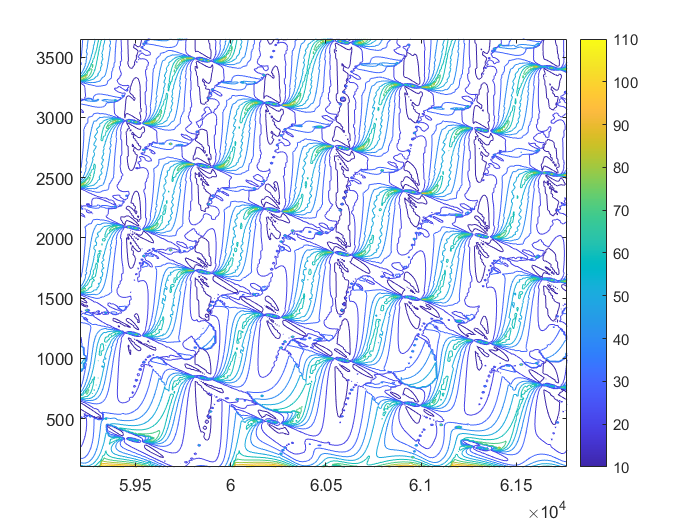

contour(dep_date_mjd,tof,pc_dv)
colorbar

## Call to NASA JPL Horizons

% Earth 1 year ephemerides
epoch_start = '2021-01-01'
epoch_stop = '2022-01-01'
step = '10d'
type_elements = 'Vectors'

data_Earth = py.neo_api_function.get_earth_ephemerides(py.str(epoch_start), py.str(epoch_stop),py.str(step),py.int(req_max_tof),py.str(type_elements))